# Example 3

This example shows how to deal with parameters in matrix form. 

Moreover, this example presents the available algorithms in the solver.

We consider the optimization problem


$$\begin{array}{ccccc}
 & \underset{x_1 ,x_2 }{minimize} ~~ &  & a(x_1 -\ldotp 5)^4 +b(x_2 -1)^4  & \\
 & \textrm{subject}\;\textrm{to}~~ &  & -1 & \le x_1^2 ,\\
 &  &  & -1 & \le x_2^2 ,\\
 &  &  & Ax & \le b,
\end{array}$$


where  $u=5,\;A=\left\lbrack \begin{array}{cc}
-3 & 1\\
2 & 1\\
0\ldotp 5 & -1
\end{array}\right\rbrack \;,b=\left\lbrack \begin{array}{c}
-6\\
14\\
-1\ldotp 5
\end{array}\right\rbrack ,x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$

 clc  
 clear  


 

x = sym('x', [2 1], 'real')

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$


A = sym('A', [3 2], 'real');
b = sym('b', [3 1], 'real')

$$b = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3} \end{array}\right)$$

syms u real; 

decision_variables= x  % the decision variables names of the optimization problem 

$$decision\_variables = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

parameters        = [reshape(A,[],1);b;u]  % to convert the matrix to vector form we use reshape

$$parameters = \left(\begin{array}{c} A_{1,1}\\ A_{2,1}\\ A_{3,1}\\ A_{1,2}\\ A_{2,2}\\ A_{3,2}\\ b_{1}\\ b_{2}\\ b_{3}\\ u \end{array}\right)$$


f_0 =  ( x(1)-.5)^4 + u*(x(2)-1)^4; % the cost function 
f_i=[    -1        <=x(1)^2
         -1        <=x(2)^2
         A*x       <=  b     ]; %the inequality constraints  %the inequality constraints

equality=[];       %the equality constraints is empty

% algorithm = 'slack_barrier'         % slack barrier solver: this algorithm does NOT require feasible point 
%algorithm = 'primal_dual_standard'  % primal dual solver: this algorithm does require feasible start  point 
algorithm = 'barrier'               % barrier solver: this algorithm does require feasible start point 

algorithm = 'barrier'

% algorithm    = 'primal_dual'          % primal dual with: this algorithm does NOT require feasible start point 

## 1- Newton step :

  Option.elimination=1; % this option builds the Newton step based on the reduced KKT system (save time)
  Option.data_recording=1; % with this option the solver does not record ever iteration data (save time and memory)
  
    
  
  NewtonStep = KKT(decision_variables,f_0,f_i,equality,parameters,algorithm,Option);

option.data_recording=1
option.elimination=0
option.function_structure='@(in1,in2)[matrix]'
option.update_dual=1
option.find_feasible_point=1


## call the solver

online calculation

x_initial =[4;5];    
A_subs= [-3  1 
          2  1 
         .5 -1];
b_subs =[-6 ;+14;-1.5]; 
u_subs =   5  ;

parameters_subs = [reshape(A_subs,[],1) ;b_subs;u_subs]; 
solver_IPsolver = IPsolver(NewtonStep,x_initial,parameters_subs);      

Barrier algorithm. Iteration number 1
Barrier algorithm. Iteration number 2
Barrier algorithm. Iteration number 3
Barrier algorithm. Iteration number 4
Barrier algorithm. Iteration number 5
Barrier algorithm. Iteration number 6
Barrier algorithm. Iteration number 7


## 1- Comparing with fmincon:

% we have built an interface for fmincon with symbolic variables    
 [solver_fmincon] =  fmincon_interface(decision_variables,f_0, f_i,equality,x_initial,parameters,parameters_subs);    


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<<a href = "matlab: createExitMsg({'optimlib:sqpLineSearch:Exit1basic'},{'optimlib:sqpLineSearch:Exit1detailed','2.874431e-07','1.000000e-06','0.000000e+00','1.000000e-06'},true,true);;">stopping criteria details</a

## Results harvesting 


% 1-  Mysolver 
n_iterations   =  solver_IPsolver.num_iteration;
x_optimal     =  solver_IPsolver.x_optimal;
cost_value     =  solver_IPsolver.cost_value;
disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('1- IPsolver')

1- IPsolver


disp(["Number of the iterations:"+n_iterations])

Number of the iterations:7


text_show= "The solver of the optimization problem: x1="+ x_optimal(1) +" and x2=" +x_optimal(2) ;
disp(text_show);

The solver of the optimization problem: x1=3 and x2=3


disp(["The cost value:"+cost_value])

The cost value:119.0625


text_show = "The calculation time for is: ("+solver_IPsolver.solver_time*1000 +") ms";
disp(text_show);

The calculation time for is: (43.9175) ms


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


% 2- fmincon solver using interior-point algorithm
n_iterations_fmincon  =  solver_fmincon.num_iteration;
x_optimal_fmincon     =  solver_fmincon.x_optimal;
cost_value_fmincon    =  solver_fmincon.cost_value;
disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


disp('2- fmincon solver using interior-point algorithm')

2- fmincon solver using interior-point algorithm


disp(["Number of the iterations:"+n_iterations_fmincon])

Number of the iterations:9


text_show= "The solver of the optimization problem: x1="+ x_optimal_fmincon(1) +" and x2=" +x_optimal_fmincon(2) ;
disp(text_show);

The solver of the optimization problem: x1=3 and x2=3


disp(["The cost value:"+cost_value_fmincon])

The cost value:119.0629


text_show = "The calculation time is ("+solver_fmincon.solver_time*1000 +") ms";
disp(text_show);

The calculation time is (37.9087) ms


disp('~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~')

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


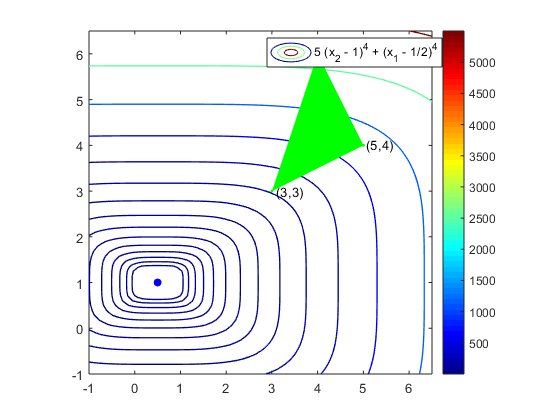


 
% constraints drawing

%ponint: (3,3), (4,6),(5,4)
%x2<=2*x1-6
% x2>=-2*x1+14
% x2<.5*x1+3/2
f=f_0;
f=subs(f_0,parameters,parameters_subs);

p1=fcontour((f),[-1,6.5],'LineWidth', 1);
levels=logspace((log10(0.1)),(log10(5500)),15)';
p1.LevelList = levels;
hold on
scat1=scatter([3,4,5],[3,6,4],5,'g','filled');
scat3=scatter([.5],[1],'bo','filled');

t1= text(3.09,3.01,'(3,3)','FontSize',10);
t1= text(4.05,6.04,'(4,6)','FontSize',10);
t1= text(5.05,4.04,'(5,4)','FontSize',10);


%t1= text(0.55,1.04,'(0.5,1)','FontSize',10);

A = [3,4,5] ;% x coordinates ;
B=  [3,6,4] ;% y coordintes;
C = [ -13,13] ;% x coordinates ;
%l3= plot(A,B,'black' ,'LineWidth', 1);
polytope= patch(A,B,'g');
polytope.EdgeColor='none';
h = legend(p1 ,'Location', 'Best');
 h.Interpreter = 'tex';
 axis equal
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
 % set(gcf, 'Units', 'Normalized', 'Position', [0, 0.04, .7, .6]);
bar= colorbar;
colormap(jet)
plot=gca;
plot.XLim = [-1 6.5];
plot.YLim = [-1 6.5];

 plot.Units='Pixels';
 shg
 
%}

